# How can I create an impulse (delta) signal in Simulink?

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2024_08_05_Impulse/2024_08_05_Impulse.prj)

Here is another commonly visited page on [MATLAB Answers](https://www.mathworks.com/matlabcentral/answers/index):

[How can I create an impulse (delta) signal in Simulink?](https://www.mathworks.com/matlabcentral/answers/399024-how-can-i-create-an-impulse-delta-signal-in-simulink)

## The Problem

Let's first look at what Wikipedia has to say about the [Dirac delta function](https://en.wikipedia.org/wiki/Dirac_delta_function):

"*In *[*mathematical analysis*](https://en.wikipedia.org/wiki/Mathematical_analysis)*, the ****Dirac delta function**** (or ****δ distribution****), also known as the ****unit impulse****,*[*[1]*](https://en.wikipedia.org/wiki/Dirac_delta_function#cite_note-FOOTNOTEatis2013unit_impulse-1)* is a *[*generalized function*](https://en.wikipedia.org/wiki/Generalized_function)* on the *[*real numbers*](https://en.wikipedia.org/wiki/Real_numbers)*, whose value is zero everywhere except at zero, and whose *[*integral*](https://en.wikipedia.org/wiki/Integral)* over the entire real line is equal to one.*[*[2]*](https://en.wikipedia.org/wiki/Dirac_delta_function#cite_note-FOOTNOTEArfkenWeber200084-2)[*[3]*](https://en.wikipedia.org/wiki/Dirac_delta_function#cite_note-FOOTNOTEDirac1930%C2%A722_The_''%CE%B4''_function-3)[*[4]*](https://en.wikipedia.org/wiki/Dirac_delta_function#cite_note-FOOTNOTEGelfandShilov1966%E2%80%931968Volume_I,_%C2%A71.1-4)* Since there is no function having this property, modelling the delta "function" rigorously involves the use of *[*limits*](https://en.wikipedia.org/wiki/Limit_(mathematics))* or, as is common in mathematics, *[*measure theory*](https://en.wikipedia.org/wiki/Measure_theory)* and the theory of *[*distributions*](https://en.wikipedia.org/wiki/Distribution_(mathematics))."

In its ideal form, the impulse should have an infinite amplitude at t=0

and the area under the curve should be 1:

In other words, the Dirac delta function is a theoretical concept that cannot really be simulated.

## Impulse Response

Before seeing how to implement a Dirac delta function in Simulink, let's talk a bit about why would someone need that.

If you are looking into implementing an impulse or Dirac delta function, it's very likely that you want to compute the [impulse response](https://en.wikipedia.org/wiki/Impulse_response) of a system. Computing the impulse response is a common way to characterize the dynamic response of a system. This is used in many areas like vibrations and acoustics.

As an example, let’s define a system with two poles, one at 5 rad/sec and one at 50 rad/sec.

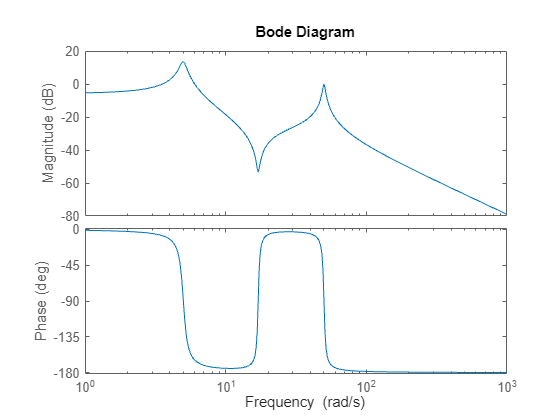

sys = tf(12,[1 0.5 25]) + tf(100,[1 2 2500]);
figure
bode(sys)

As a reference, let's start with the [impulse](https://www.mathworks.com/help/releases/R2024a/control/ref/dynamicsystem.impulse.html) function from the [Control System Toolbox](https://www.mathworks.com/products/control.html) to see how the system responds to an impulse.

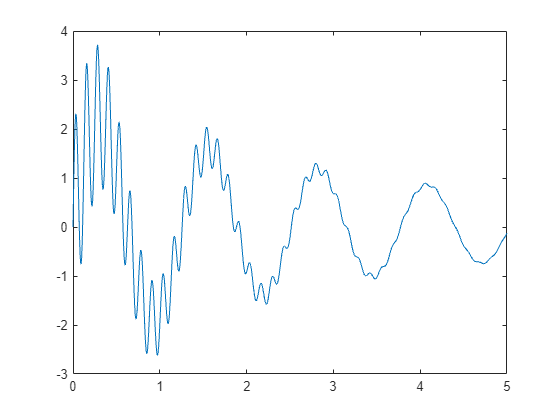

tFinal = 5;
[y,t] = impulse(sys,tFinal);
figure
plot(t,y)

Let's now look at how something similar could be implemented in Simulink.

## Fixed-Step Solver

The implementation of an impulse in Simulink will probably be different if implemented fixed versus variable step. Let's begin with the fixed-step case.

With a discrete signal, the [Hit Crossing](https://www.mathworks.com/help/releases/R2024a/simulink/slref/hitcrossing.html) block outputs a value of 1 for one time step when the specified hit crossing offset is crossed. To respect the Dirac definition that the area under the curve must be equal to 1, we can divide this signal by the sample time.

mdl = "impulse_ex_discrete";
open_system(mdl);

In this example, I want to trigger the impulse to happen when the output of the [Digital Clock](https://www.mathworks.com/help/releases/R2024a/simulink/slref/digitalclock.html) block crosses a specific value, let's say 1 second.

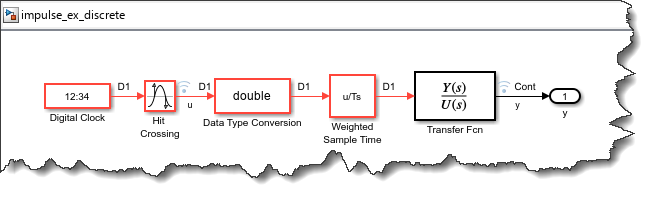

Using the same transfer function as in our previous example, we can see that the results match.

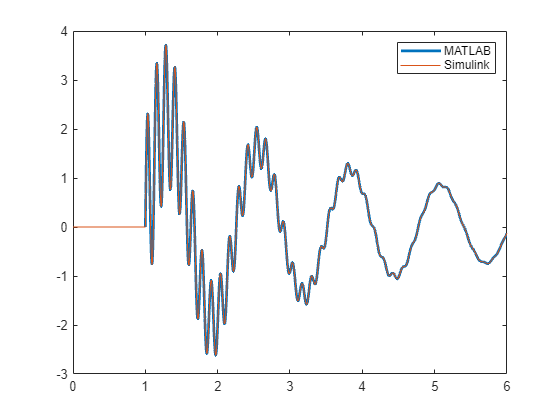

out = sim(mdl);
figure;
plot(t+1,y,'LineWidth',2) % Offset the time reference by 1 second
hold on
plot(out.yout{1}.Values)
legend('MATLAB','Simulink')

## Variable-Step Solvers

With a variable-step solver, there are a few subtle things that you need to take care of.

#### Impulse at t=0

If what you need is an impulse at t=0, I recommend using the [Step](https://www.mathworks.com/help/releases/R2024a/simulink/slref/step.html) block. This will allow you to control the amplitude and duration of the pulse.

mdl = "impulse_ex_1";
open_system(mdl);

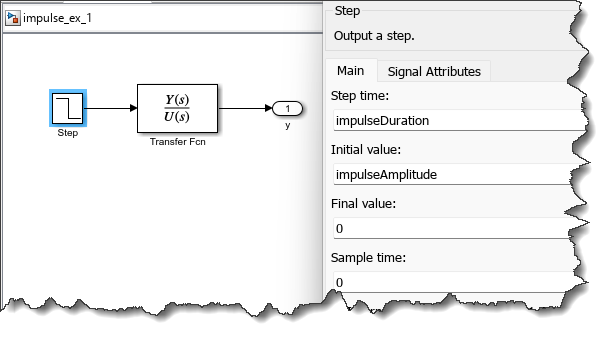

The important thing to decide is the value to use for the duration and amplitude of the impulse. Since this is impossible to generate an infinitely large amplitude with an infinitely small width, we need to pick a number. 

Let's simulate the model with different values for the amplitude and width of the impulse. To respect the assumption that the integral of the pulse is 1, I make the amplitude the inverse of the duration.

p = [1e-6 0.1 1];
in = repmat(Simulink.SimulationInput(mdl),length(p),1);
for i = 1:length(in)
    in(i) = in(i).setVariable('impulseDuration',p(i));
    in(i) = in(i).setVariable('impulseAmplitude',1/p(i));
end
out = sim(in,'ShowProgress','off');

The key thing to realize is that the longer the duration of the impulse, the more it becomes a step instead of an impulse. In the Laplace world, an ideal Diract delta function has an amplitude of 1 for all frequencies, while a step has an amplitude of $1/s$. The longer the impulse, the less it excites high frequencies.

Looking at the results, we can see that the second mode at 50 rad/sec is significantly less excited when the duration of the step becomes longer.

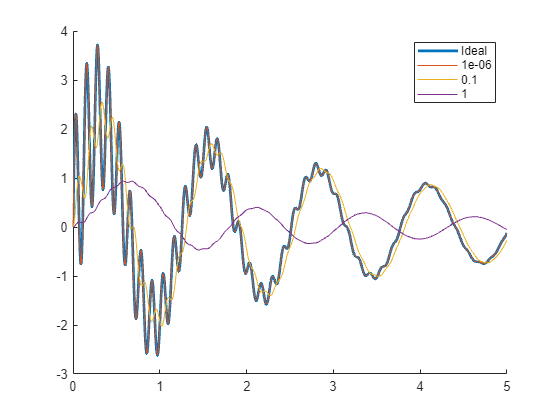

figure;hold on;
plot(t,y,'LineWidth',2)
for i = 1:length(out)
    plot(out(i).yout{1}.Values)
end
legend(['Ideal' arrayfun(@num2str, p, 'UniformOutput', false)])

#### Impulse at times other than zero

While the definition of the Dirac delta function says it should return a non-zero value only at t=0, it can be useful to generate an impulse at other times. 

As a first attempt, it would be tempting to use a pattern similar to the one used for fixed-step. The challenge here is that with a variable-step solver, we don't have direct control on the duration of the pulse generated by the Hit Crossing block.

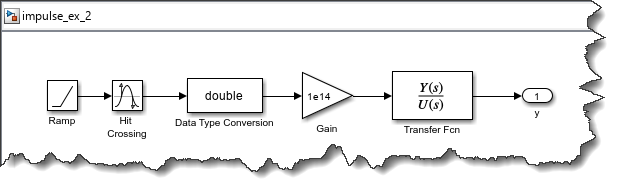

Based on what I know from [zero-crossing detection](https://www.mathworks.com/help/releases/R2024a/simulink/ug/zero-crossing-detection.html), I guessed a gain value of 1e14 for the amplitude of the pulse, but we can see that it's not quite right.

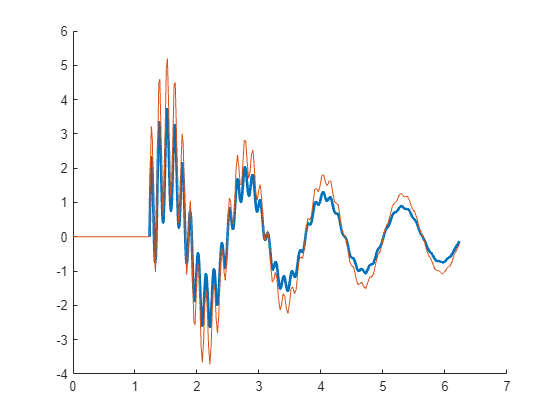

mdl = 'impulse_ex_2';
in = Simulink.SimulationInput(mdl);
out = sim(in);
figure;hold on;
plot(t+1.23456,y,'LineWidth',2)
plot(out.yout{1}.Values)

#### Scheduling the Impulse Duration

To control the duration of the impulse, it is possible to use the [Hit Scheduler](https://www.mathworks.com/help/releases/R2024a/simulink/slref/hitscheduler.html) block. When the time to trigger the impulse is detected by the Hit Crossing block we do two things: First, the event `TrigOn` is sent to the [Stateflow](https://www.mathworks.com/products/stateflow.html) chart to initiate the impulse. Then the Hit Scheduler schedules a second event `TrigOff` to be sent to the chart after a specified amount of time to terminate the impulse.

mdl1 = "impulse_ex_2c";
open_system(mdl1);

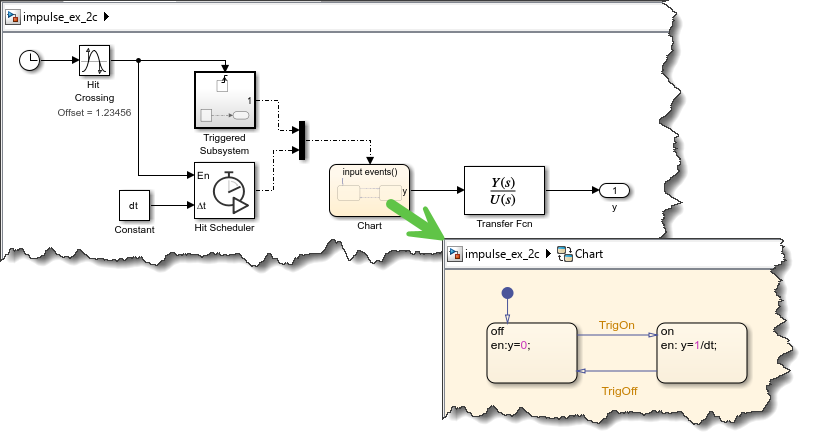

If you prefer, you can slightly simplify the logic by using the [Discrete-Event Chart](https://www.mathworks.com/help/releases/R2024a/simevents/ref/discreteeventchart.html) from [SimEvents](https://www.mathworks.com/products/simevents.html). In that case, you would configure the Hit Crossing block to output a message instead of a signal. This message will wake up the chart, and the chart will keep the impulse on for a duration specified using [after](https://www.mathworks.com/help/releases/R2024a/stateflow/ref/after.html). 

mdl2 = "impulse_ex_2b";
open_system(mdl2);

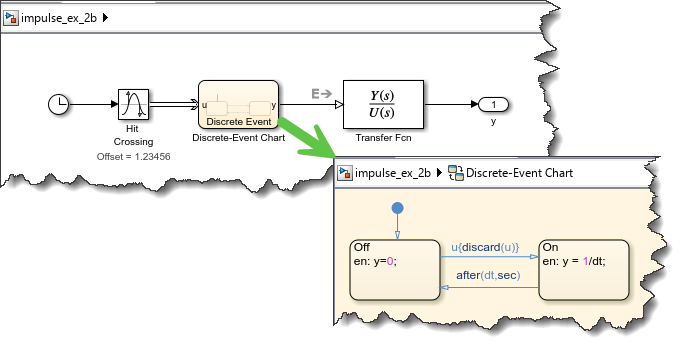

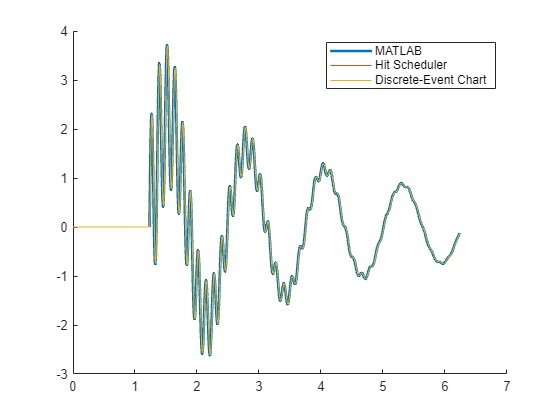

out1 = sim(mdl1);
out2 = sim(mdl2);
figure;hold on;
plot(t+1.23456,y,'LineWidth',2)
plot(out1.yout{1}.Values)
plot(out1.yout{1}.Values)
legend("MATLAB", "Hit Scheduler", "Discrete-Event Chart");

## Approximation using a normal distribution

If you took the time to read the[ Wikipedia page on the Dirac delta function](https://en.wikipedia.org/wiki/Dirac_delta_function), you might have noticed that another option is to implement the impulse as a normal distribution in the form:

To implement that, I can use the same logic as before to initiate and terminate the pulse. Instead of just outputting an on/off signal, I can use an Enabled Subsystem to "play" the normal distribution function.

mdl = "impulse_ex_3_b";
open_system(mdl);

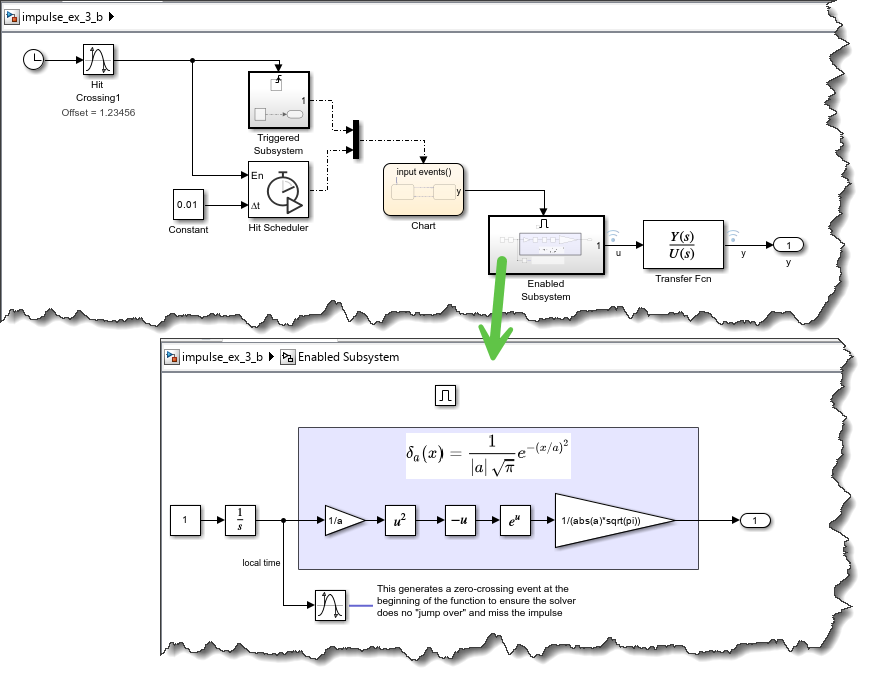

out = sim(mdl);

In this case, we can see that the results match what we got from the `impulse` function.

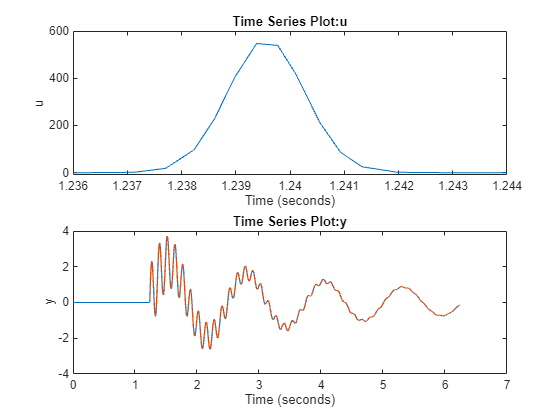

figure;
subplot(2,1,1)
plot(out.logsout.get('u').Values)
axis([1.236 1.244 -10 600]);
subplot(2,1,2)
plot(out.logsout.get('y').Values)
hold on% compare to reference
plot(t+1.23456,y)

## Now it's your turn

Have fun implementing impulses or Dirac delta functions in your Simulink model. If you have other techniques, share in the comments below.